# CSX/ECE 6730 Project 1: Cowell's Method

**Team 57: Blaine Costello, Caitlyn Caggia, Lakshmi Raju**

**Spring 2019**

## Cowell's Method Background

Cowell's method for orbital simulation simply sums the Newtonian forces on a body of *i *from the other bodies *j:*


$$\ddot{\mathbf{r}}_i = \sum_{j=1,{j \neq i}}^{n}   \frac{Gm_{j}( \mathbf{r}_j - \mathbf{r}_i)}{r_{ij}^3}$$


where

    $\ddot{\mathbf{r}}_i$ is the acceleration vector of body *i*

*    G *is the gravitational constant ($6.674 \times 10^{-11} \:\mathrm{m}^{3} \,\mathrm{kg}^{-1} \,\mathrm{s}^{-2}$)

    $m_j
$ is the mass of body j

    $\mathbf{r}_i$ and $\mathbf{r}_j$ are the position vectors of objects *i * and *j*

    $r_{ij}$ is the distance from object *i* to object *j*

with all vectors relative to the barycenter of the system.

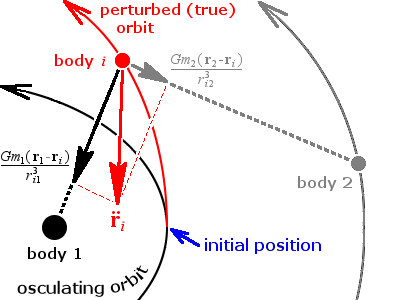

*Forces from preturbing bodies (black and gray) are summed to form the total force on the body of interest (red). Thus the true (red) orbit deviates from the original unpreturbed orbit (black). Image courtesy of *[*Wikimedia*](https://upload.wikimedia.org/wikipedia/commons/3/30/Cowells_method.png)*. *

While this method is the among the simplest to use, it has high error when handling large perturbations (for example, when two objects nearly miss each other) and requires a large degree of arithmetic precision when the mass of the bodies varies greatly.

## Input Setup

**Mass Data**

Masses of the Sun and 9 planets (Mercury, Venus, Earth, Moon, Mars, Jupiter, Saturn, Uranus, Neptune, Pluto, respectively) courtesy of [NASA](https://nssdc.gsfc.nasa.gov/planetary/factsheet/). Mass is saved as a 1xN vector in kilograms.

                   % Sun  Merc  V    E    Moon  Mars  J    S   U    N   P
 masses = 10^24.*[1988500 0.330 4.87 5.97 0.073 0.642 1898 568 86.8 102 0.0146]; % [kg]
 N = length(masses); % Number of bodies

**Position and Velocity Data**

Note that to use this data, you need Matlab's Aerospace Toolbox (available with the Georgia Tech's Matlab licenses for free) as well as the Ephemeris Data add-on available through [Mathworks](https://www.mathworks.com/matlabcentral/fileexchange/46671-ephemeris-data-for-aerospace-toolbox) for free. These packages use data from NASA's Jet Propulsion Laboratory (JPL) ephemeris [database](https://ssd.jpl.nasa.gov/?planet_eph_export).

The barycenter of the Solar System is used as the observation point of reference as of January 1, 2000.  Distances are in km and velocities are in km/s. Positions and velocities are saved in 3xN vectors.

[posSun, velSun] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Sun');
[posMerc, velMerc] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Mercury');
[posV, velV] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Venus');
[posE, velE] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Earth'); 
[posMoon, velMoon] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Moon');
[posMars, velMars] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Mars');
[posJ, velJ] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Jupiter');
[posS, velS] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Saturn');
[posU, velU] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Uranus');
[posN, velN] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Neptune');
[posP, velP] = planetEphemeris(juliandate(2000,1,1),'SolarSystem','Pluto');

positions = [posSun(:) posMerc(:) posV(:) posE(:) posMoon(:) posMars(:) posJ(:) ...
    posS(:) posU(:) posN(:) posP(:)]; % [km]
velocities = [velSun(:) velMerc(:) velV(:) posE(:) velMoon(:) velMars(:) velJ(:) ...
    velS(:) velU(:) velN(:) velP(:)]; % [km/s]

## Vector Solver

[Description to be added]

G = 6.674e-11; % Gravitational constant
accel = 0;

% Influence of the other 10 bodies on the Earth
for tstep = 1:T
    accel = zeros(3,N); 
    for i = 1:N
        for j = 1:N
            if i ~= j
                d = sqrt((positions(1,j)-positions(1,i))^2 + ...
                    (positions(2,j)-positions(2,i))^2 + ...
                    (positions(3,j)-positions(3,i))^2);
                accel(1,i) = (accel(1,i)+(G*masses(j)*(positions(1,j)...
                    -positions(1,i))) / (d.^3));
                accel(2,i) = (accel(2,i)+(G*masses(j)*(positions(2,j)...
                    -positions(2,i))) / (d.^3));
                accel(3,i) = (accel(3,i)+(G*masses(j)*(positions(3,j)...
                    -positions(3,i))) / (d.^3));
            end
        end
    end
end

## Plot Generator

[Description to be added]

%Code to be added